clear all

### データベースの読み込み

AMP_TYPE = "a";
SUPPLY_TYPE = "clean";
DATA_PATH  = "./data/processed/";
data_strct = load(DATA_PATH +"amp_"+AMP_TYPE+"/"+SUPPLY_TYPE+".mat")

data_strct = フィールドをもつ struct :
    clean: [1×1 struct]


### 解析データの取得

%解析するデータの指定
poly_type = "aa";
freq_type = 4;
vpp_type = 1;
trial_type = 1;

%読み込み
data = data_strct.(SUPPLY_TYPE).(poly_type).freq(freq_type).vpp(vpp_type).trial(trial_type).signal;

### データの切り抜き処理

信号の読み込み

n = 1;
signal = data(:,n);
len_sig = length(signal)

len_sig = 528000

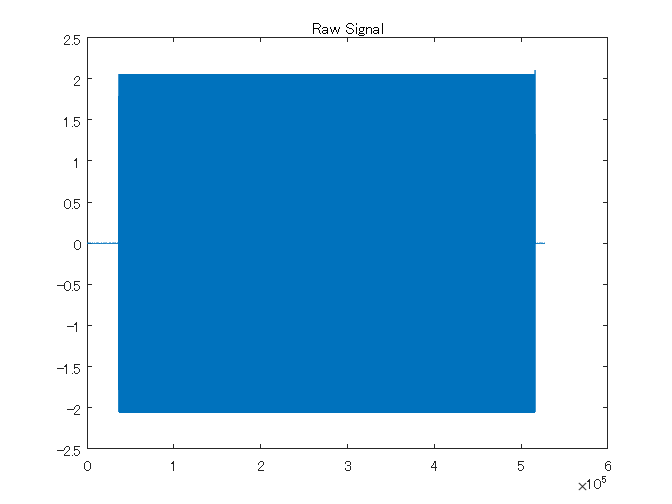


figure(1)
plot(signal)
title("Raw Signal")

前後の無音区間の切り抜き

flag1 = false;
flag2 = false;
for i = 1:len_sig

    % 前方の切り出し
    if abs(signal(i)) > max(signal)*0.8 && ~flag1
        start_sig = i;
        flag1 = true;
    end
    
    % 後方の切り出し
    if abs(signal(len_sig+1-i))>max(signal)*0.7 && ~flag2
        end_sig = len_sig-i;
        flag2 = true;
    end
    
    % 繰り返し処理の中断
    if flag1 && flag2
        break
    end
end

disp(start_sig)

       36148



disp(end_sig)

      515999



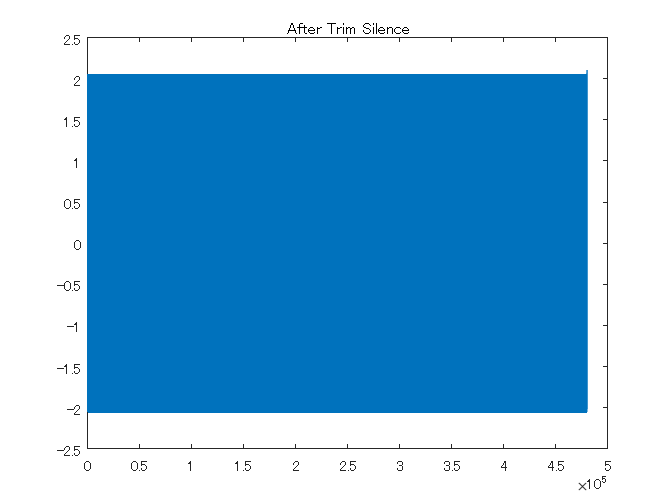

signal_trim_silence = signal(start_sig:end_sig);
figure(2)
plot(signal_trim_silence)
title("After Trim Silence")

### アップサンプリング処理

**ローパスフィルタの設計**

%Normalize a signal using interpolation an analyze it with signal

%リサンプリング後のサンプリング周波数
FsI =10*48e3;

%パラメータ
Fup=lcm(Fs,FsI)/Fs;
Fdun=lcm(Fs,FsI)/FsI;

%% ローパスフィルタの作成
N   = 300;
Fp  = Fs*0.4;
Ap  = 0.01;
Ast = 160;

%リップルの計算
Rp  = (10^(Ap/20) - 1)/(10^(Ap/20) + 1);
Rst = 10^(-Ast/20);

NUM = firceqrip(N,Fp/(FsI/2),[Rp Rst],'passedge');
% fvtool(NUM,'Fs',Fs)
delay = mean(grpdelay(NUM))

delay = 150

**リサンプリング処理の実行**

%% RESAMPLEING
signal_test = signal_trim_silence

signal_test =    -1.7749
    1.7839
   -1.7021
    0.9409
    0.0728
   -1.0663
    1.7744
   -1.7839
    1.7016
   -0.9408


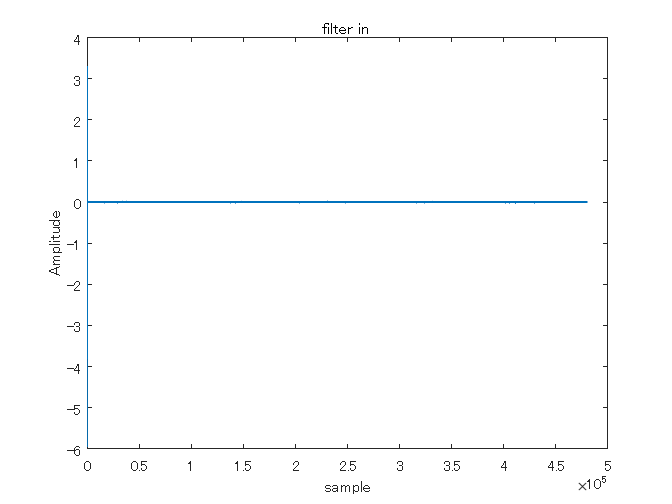

% up sampling
signal_up=upsample(signal_test,Fup);
y=filter(NUM,1,signal_up);

% reshape
ys=5*y(delay:end);

figure(10)
plot(ys);
xlabel('sample')
ylabel('Amplitude')
title('filter in ')

signal_trim_silence = ys;
Fs = FsI;
% % 
% figure(11)
% L=length(4*yy(1:end-1));
% Y = fft(4*yy(1:end-1)); 
% P2 = abs(Y/L);
% P1 = P2(1:L/2+1);
% P1(2:end-1) = 2*P1(2:end-1);
% f = FsI*(0:(L/2))/L;
% plot(f,mag2db(P1),'Linewidth',2.0)
% title('upsample - Lowpass')
% xlabel('f [Hz]')
% ylabel('Power[db]')



### 前後数周期の切り捨て

前後数サンプルはアンプの追従性能の影響で波形が汚い。

そのため、指定した周期分だけ前後のサンプルを切り捨てる。

指定した周期分のガイド波形を作成し、切り捨てるポイントを確定する。

コンストラクターの宣言

% Fs = 48e3;
f = 20000;
period = 5000;
gen = CreateSignal(Fs,f,1);

ガイド波形の生成

gaid = gen.createCosSample(period);

t_end = 0.2500

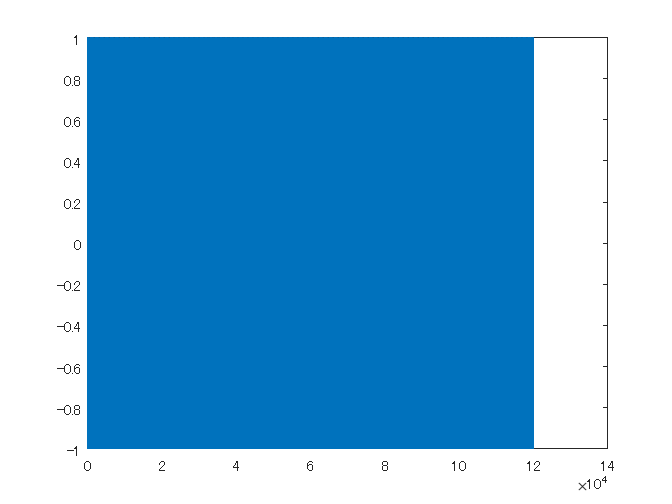

figure(3)
plot(gaid)

ガイド波形による位置合わせ

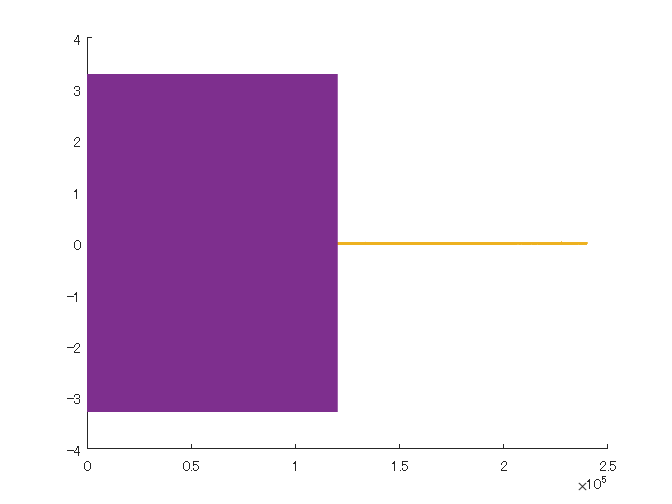

%% 新規開始点の計算
ref_start = signal_trim_silence(1:length(gaid)*2);

figure(4)
hold on
plot(ref_start(38:end))
plot(max(ref_start)*gaid)
hold off

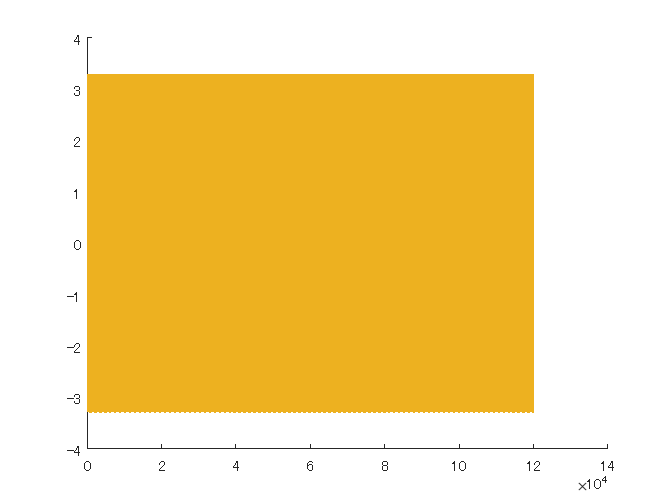


%相互相関の計算
[c,lag] = xcorr(ref_start,gaid);
c = c/max(c);
[~,I] = max(c);
start_lag = lag(I);

%何周期目で相関が最大になっているか計算
start_period = round(start_lag/(Fs/f));
start_sig = start_lag + round(Fs/f) * (period-start_period);

figure(5)
hold on
plot(max(ref_start)*gaid)

plot(signal_trim_silence(start_sig:4*length(gaid)))

インデックスが配列要素数を超えています。インデックスは 479703 を超えてはなりません。

hold off

%% 新規終了点の計算
ref_end = signal_trim_silence(length(signal_trim_silence)-length(gaid)*2:end);
ref_end = flip(ref_end);

figure(6)
hold on
plot(ref_end)
plot(max(ref_end)*gaid)
hold off

%相互相関の計算
[c,lag] = xcorr(ref_end,gaid);
c = c/max(c);
[~,I] = max(c);
end_lag = lag(I);

%何周期目で相関が最大になっているか計算
end_period = round(end_lag/(Fs/f));
end_sig = length(signal_trim_silence) - (end_lag + round(Fs/f) * (period-end_period));

figure(7)
hold on
% plot(max(ref_start)*gaid)
plot(signal_trim_silence(length(signal_trim_silence)-4*length(gaid):end_sig))
hold off

figure(8)
plot(signal_trim_silence(start_sig:end_sig))

start_sig/(Fs/f)

ans = 5.0005e+03